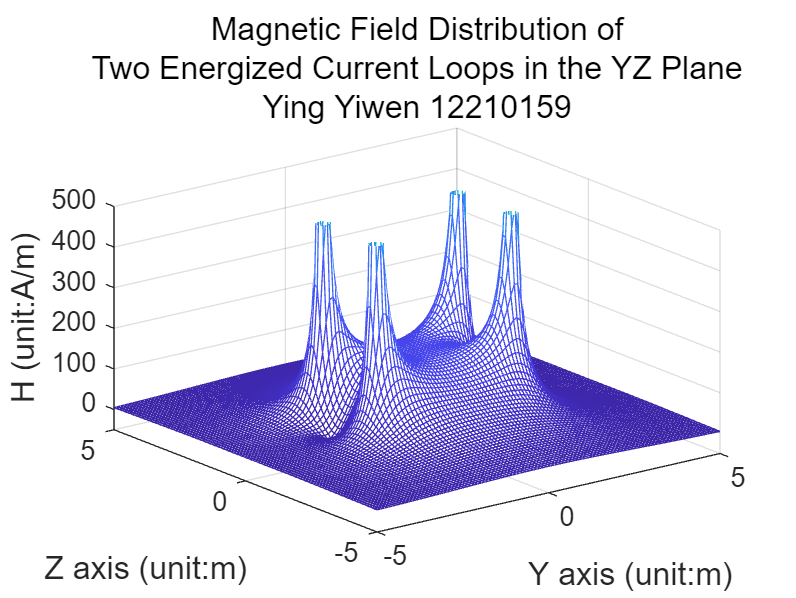

% r=2,I=500,O1(0,0,-1),O2(0,0,1),same direction
clc,clear,close all;
a=2; % radius of circuit
I=500; % current
C=I/(4*pi); % merge constant
N=200; % segments of circuit loop
ym=5; % y region
zm=5; % z region
n=100; % divide segments

y=linspace(-ym,ym,n); % divide y
z=linspace(-zm,zm,n); % divide z
[Y,Z]=meshgrid(y,z); % form coordinates
theta0=linspace(0,2*pi,N+1); % divide the circle
theta1=theta0(1:N); % start angle
x1=a*cos(theta1); % start x
y1=a*sin(theta1); % start y
theta2=theta0(2:N+1); % end angle
x2=a*cos(theta2); % end x
y2=a*sin(theta2); % end y
xc=(x1+x2)/2; % midpoint x
yc=(y1+y2)/2; % midpoint y
zc1=-ones(N); % midpoint z1
zc2=ones(N); % midpoint z2
dlx=x2-x1; % dl x
dly=y2-y1; % dl y
dlz=0; %dl z

Hy=zeros(n); % build H for y component
Hz=zeros(n); % build H for z component
H=zeros(n); % build H (total)
for i = 1:N
    X=zeros(n); % x are all zeros because on yz plane
    rx=X-xc(i); % r x
    ry=Y-yc(i); % r y
    rz1=Z-zc1(i); % r z1
    rz2=Z-zc2(i); % r z2
    r31=sqrt(rx.^2+ry.^2+rz1.^2).^3; % r^3 1
    r32=sqrt(rx.^2+ry.^2+rz2.^2).^3; % r^3 2
    dlXr_y1=-dlx(i).*rz1; % y component of dl×r 1
    dlXr_y2=-dlx(i).*rz2; % y component of dl×r 2
    dlXr_z=dlx(i).*ry-dly(i).*rx; % z component of dl×r
    Hy=Hy+C.*dlXr_y1./r31; % add to Hy 1
    Hy=Hy+C.*dlXr_y2./r32; % add to Hy 2
    Hz=Hz+C.*dlXr_z./r31; % add to Hz 1
    Hz=Hz+C.*dlXr_z./r32; % add to Hz 2
    H=(Hy.^2+Hz.^2).^0.5; % compute H
end

figure; % magnetic distribution (whole)
mesh(Y,Z,H); % draw distribution figure
hold on; % keep the same graph
title(sprintf('Magnetic Field Distribution of\nTwo Energized Current Loops in the YZ Plane\nYing Yiwen 12210159'),"FontSize",12); % title
axis([-5,5,-5,5,-50,500]); % xyz limits
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
zlabel('H (unit:A/m)','FontSize',12); % z label
saveas(gcf,'fig1-1.jpg'); % save figure

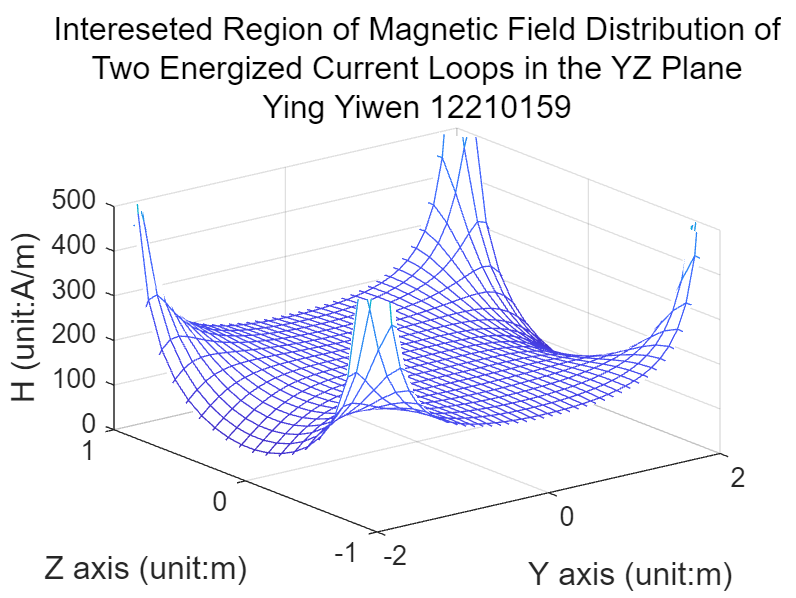

figure; % magnetic distribution (-2,2,-1,1)
mesh(Y,Z,H); % draw distribution figure
hold on; % keep the same graph
title(sprintf('Intereseted Region of Magnetic Field Distribution of\nTwo Energized Current Loops in the YZ Plane\nYing Yiwen 12210159'),"FontSize",12); % title
axis([-2,2,-1,1,-0,500]); % xyz limits
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
zlabel('H (unit:A/m)','FontSize',12); % z label
saveas(gcf,'fig1-2.jpg'); % save figure

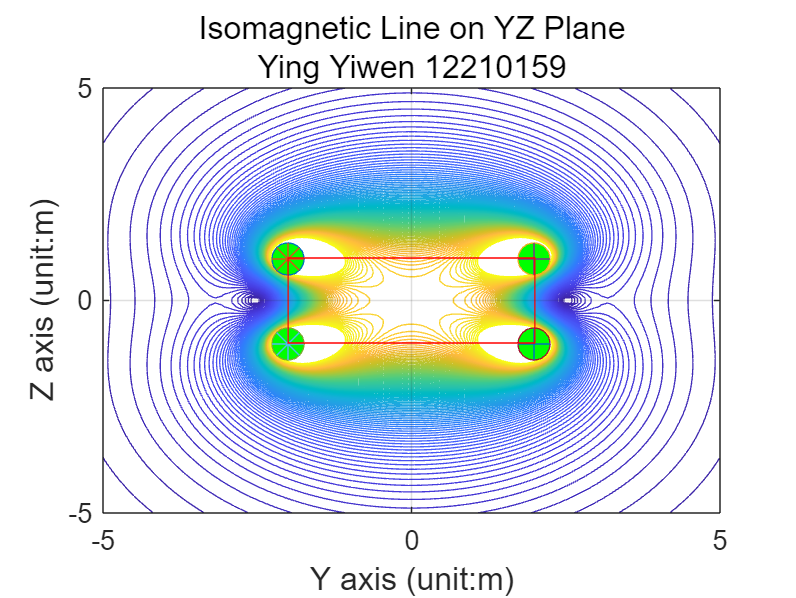


figure; % isomagnetic
Hmin=0; % minimum H
Hmax=200; % maximum H
H0=linspace(Hmin,Hmax,100); % divide isomagnetic line
contour(Y,Z,H,H0); % draw isomagnetic line
grid on; % form grid
hold on; % keep the same graph
title(sprintf('Isomagnetic Line on YZ Plane\nYing Yiwen 12210159'),"FontSize",12); % title
axis([-5,5,-5,5]); % xy limits
plot(-2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(-2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,-1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,-1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
rectangle('Position',[-2,-1,4,2],'EdgeColor','r'); % the interested region
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
saveas(gcf,'fig1-3.jpg'); % save figure

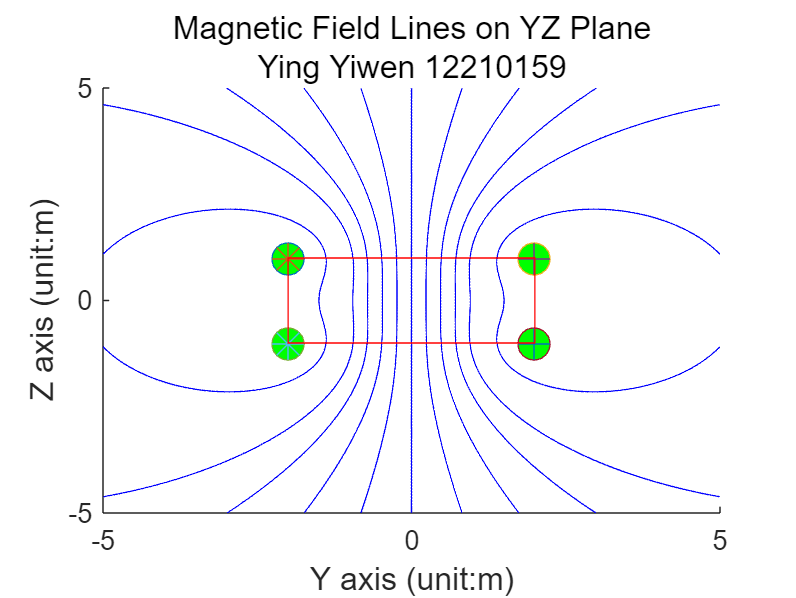


figure; % distribution of magnetic field lines
theta=[0 50 60 70 80 90 100 110 120 130 180].*pi/180; % radian value
ys=1.5*cos(theta); % field line origin coordinates x
zs=1.5*sin(theta); % field line origin coordinates y
streamline(Y,Z,Hy,Hz,ys,zs); % draw magnetic field lines outward
streamline(Y,Z,-Hy,-Hz,ys,zs); % draw magnetic field lines inward
title(sprintf('Magnetic Field Lines on YZ Plane\nYing Yiwen 12210159'),"FontSize",12); % title
hold on; % keep the same graph
axis([-5,5,-5,5]); % xy limits
plot(-2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(-2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,-1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,-1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
rectangle('Position',[-2,-1,4,2],'EdgeColor','r'); % the interested region
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
saveas(gcf,'fig1-4.jpg'); % save figure

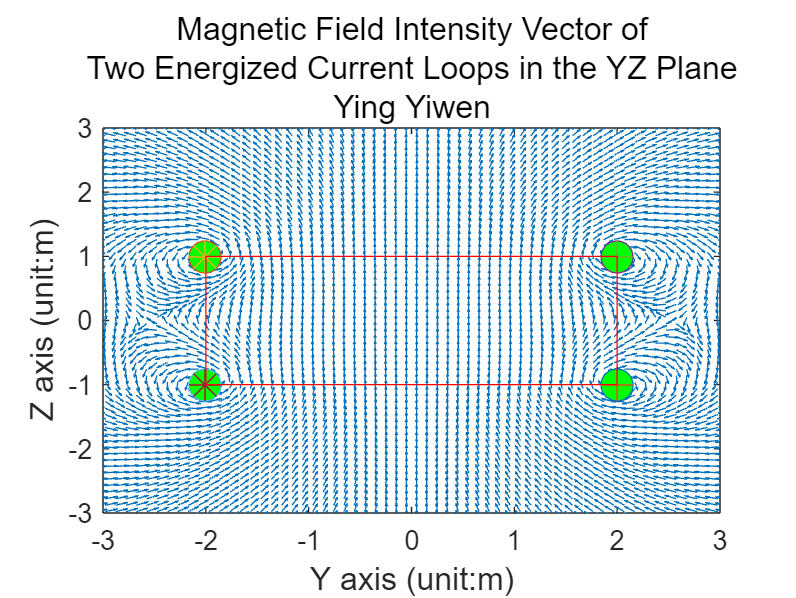


figure; % magnetic field strength vector diagram
Hy=Hy./H; % normalization
Hz=Hz./H; % normalization
quiver(Y,Z,Hy,Hz); % draw vector diagram
hold on; % keep the same graph
title(sprintf('Magnetic Field Intensity Vector of\nTwo Energized Current Loops in the YZ Plane\nYing Yiwen'),"FontSize",12); % title
axis([-3,3,-3,3]); % xy limits
plot(-2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(-2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,-1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,-1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
rectangle('Position',[-2,-1,4,2],'EdgeColor','r'); % the interested region
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
saveas(gcf,'fig1-5.jpg'); % save figure

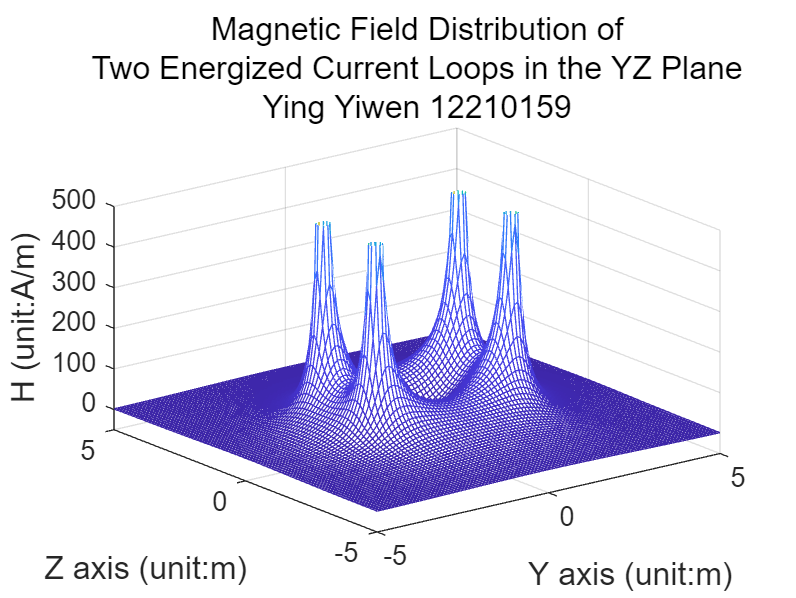

% r=2,I=500,O1(0,0,-1),O2(0,0,1),oppsite direction
clc,clear,close all;
a=2; % radius of circuit
I=500; % current
C=I/(4*pi); % merge constant
N=200; % segments of circuit loop
ym=5; % y region
zm=5; % z region
n=100; % divide segments

y=linspace(-ym,ym,n); % divide y
z=linspace(-zm,zm,n); % divide z
[Y,Z]=meshgrid(y,z); % form coordinates
theta0=linspace(0,2*pi,N+1); % divide the circle
theta1=theta0(1:N); % start angle
x1=a*cos(theta1); % start x
y1=a*sin(theta1); % start y
theta2=theta0(2:N+1); % end angle
x2=a*cos(theta2); % end x
y2=a*sin(theta2); % end y
xc=(x1+x2)/2; % midpoint x
yc=(y1+y2)/2; % midpoint y
zc1=-ones(N); % midpoint z1
zc2=ones(N); % midpoint z2
dlx=x2-x1; % dl x
dly=y2-y1; % dl y
dlz=0; %dl z

Hy=zeros(n); % build H for y component
Hz=zeros(n); % build H for z component
H=zeros(n); % build H (total)
for i = 1:N
    X=zeros(n); % x are all zeros because on yz plane
    rx=X-xc(i); % r x
    ry=Y-yc(i); % r y
    rz1=Z-zc1(i); % r z1
    rz2=Z-zc2(i); % r z2
    r31=sqrt(rx.^2+ry.^2+rz1.^2).^3; % r^3 1
    r32=sqrt(rx.^2+ry.^2+rz2.^2).^3; % r^3 2
    dlXr_y1=dlx(i).*rz1; % y component of dl×r 1
    dlXr_y2=-dlx(i).*rz2; % y component of dl×r 2
    dlXr_z1=-dlx(i).*ry+dly(i).*rx; % z component of dl×r 1
    dlXr_z2=dlx(i).*ry-dly(i).*rx; % z component of dl×r 2
    Hy=Hy+C.*dlXr_y1./r31; % add to Hy 1
    Hy=Hy+C.*dlXr_y2./r32; % add to Hy 2
    Hz=Hz+C.*dlXr_z1./r31; % add to Hz 1
    Hz=Hz+C.*dlXr_z2./r32; % add to Hz 2
    H=(Hy.^2+Hz.^2).^0.5; % compute H
end

figure; % magnetic distribution (whole)
mesh(Y,Z,H); % draw distribution figure
hold on; % keep the same graph
title(sprintf('Magnetic Field Distribution of\nTwo Energized Current Loops in the YZ Plane\nYing Yiwen 12210159'),"FontSize",12); % title
axis([-5,5,-5,5,-50,500]); % xyz limits
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
zlabel('H (unit:A/m)','FontSize',12); % z label
saveas(gcf,'fig2-1.jpg'); % save figure

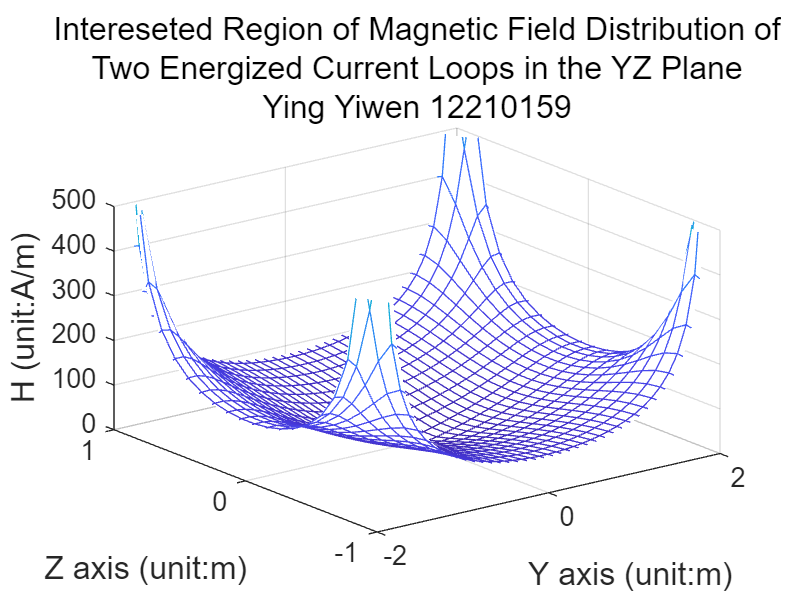

figure; % magnetic distribution (-2,2,-1,1)
mesh(Y,Z,H); % draw distribution figure
hold on; % keep the same graph
title(sprintf('Intereseted Region of Magnetic Field Distribution of\nTwo Energized Current Loops in the YZ Plane\nYing Yiwen 12210159'),"FontSize",12); % title
axis([-2,2,-1,1,-0,500]); % xyz limits
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
zlabel('H (unit:A/m)','FontSize',12); % z label
saveas(gcf,'fig2-2.jpg'); % save figure

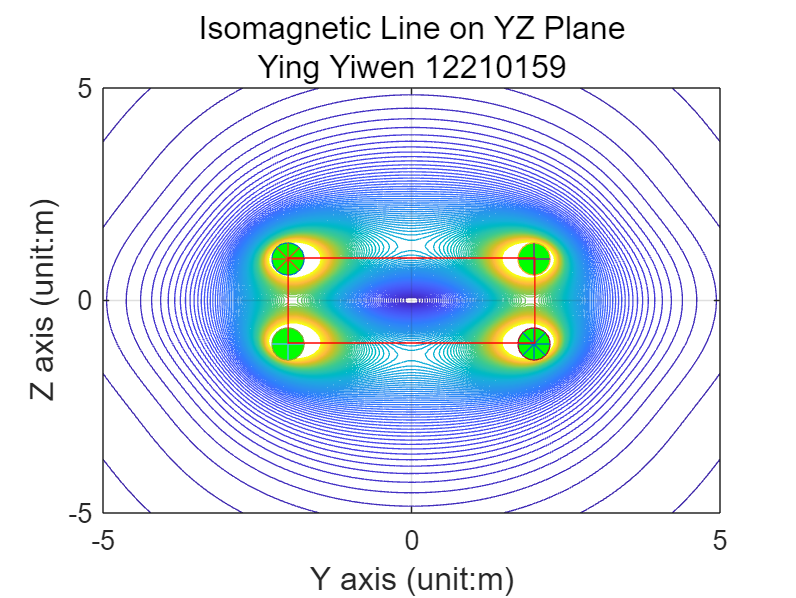


figure; % isomagnetic
Hmin=0; % minimum H
Hmax=200; % maximum H
H0=linspace(Hmin,Hmax,100); % divide isomagnetic line
contour(Y,Z,H,H0); % draw isomagnetic line
grid on; % form grid
hold on; % keep the same graph
title(sprintf('Isomagnetic Line on YZ Plane\nYing Yiwen 12210159'),"FontSize",12); % title
axis([-5,5,-5,5]); % xy limits
plot(-2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(-2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,-1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,-1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
rectangle('Position',[-2,-1,4,2],'EdgeColor','r'); % the interested region
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
saveas(gcf,'fig2-3.jpg'); % save figure

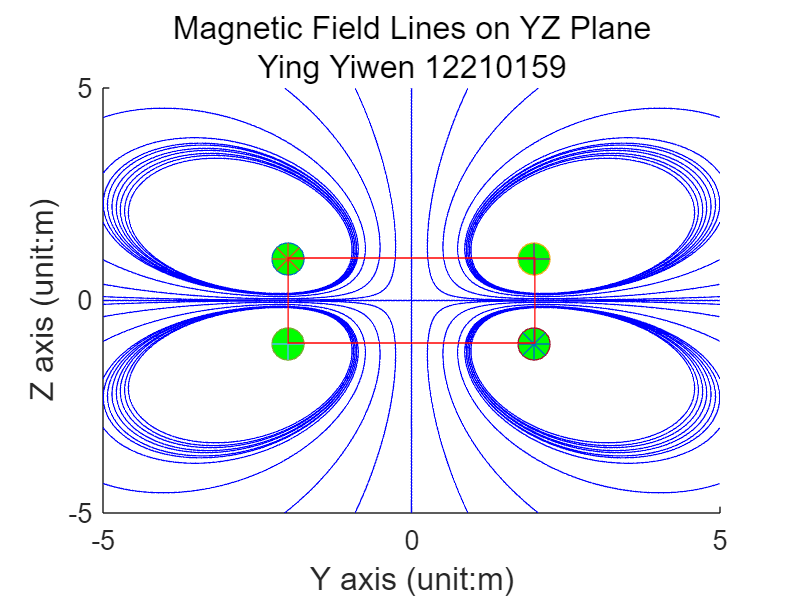


figure; % distribution of magnetic field lines
theta=[0 50 60 70 80 90 100 110 120 130 180 230 240 250 260 270 280 290 300 310].*pi/180; % radian value
ys=1.5*cos(theta); % field line origin coordinates x
zs=1.5*sin(theta); % field line origin coordinates y
streamline(Y,Z,Hy,Hz,ys,zs); % draw magnetic field lines outward
streamline(Y,Z,-Hy,-Hz,ys,zs); % draw magnetic field lines inward
title(sprintf('Magnetic Field Lines on YZ Plane\nYing Yiwen 12210159'),"FontSize",12); % title
hold on; % keep the same graph
axis([-5,5,-5,5]); % xy limits
plot(-2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(-2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,-1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,-1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
rectangle('Position',[-2,-1,4,2],'EdgeColor','r'); % the interested region
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
saveas(gcf,'fig2-4.jpg'); % save figure

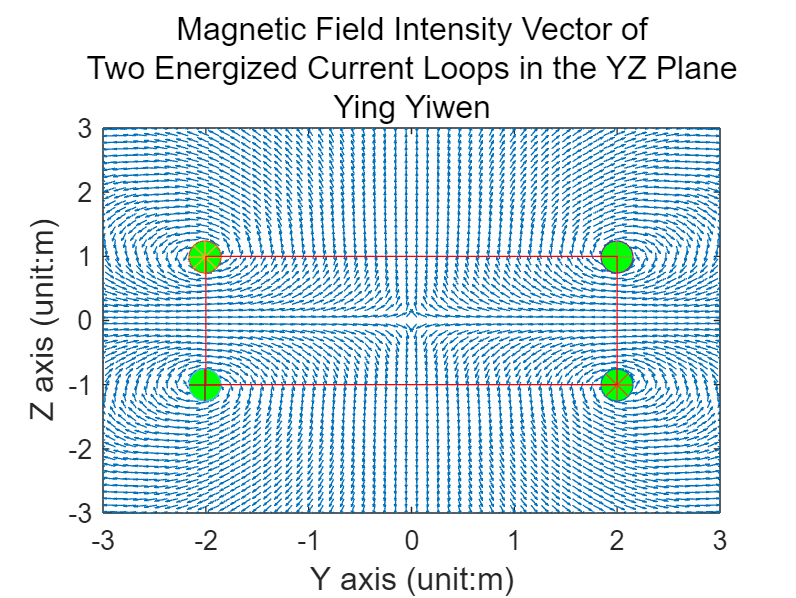


figure; % magnetic field strength vector diagram
Hy=Hy./H; % normalization
Hz=Hz./H; % normalization
quiver(Y,Z,Hy,Hz); % draw vector diagram
hold on; % keep the same graph
title(sprintf('Magnetic Field Intensity Vector of\nTwo Energized Current Loops in the YZ Plane\nYing Yiwen'),"FontSize",12); % title
axis([-3,3,-3,3]); % xy limits
plot(-2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(-2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (-2,1) bisect
plot(-2,-1,'+','MarkerFaceColor','k','MarkerSize',12); % current flow direction
plot(2,-1,'o','MarkerFaceColor','g','MarkerSize',12); % (2,1) bisect
plot(2,-1,'*','MarkerFaceColor','k','MarkerSize',12); % current flow direction
rectangle('Position',[-2,-1,4,2],'EdgeColor','r'); % the interested region
xlabel('Y axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % y label
saveas(gcf,'fig2-5.jpg'); % save figure